# **Introductory script illustrating how to generate a TreeShrew optics model**

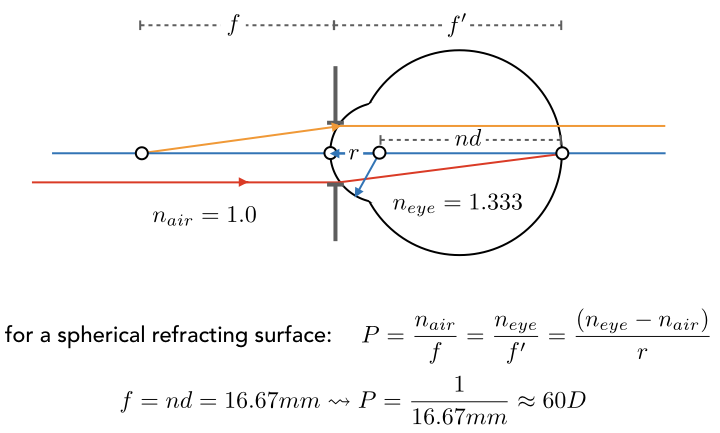

humanCornealRadiusMM = 5.56

humanCornealRadiusMM = 5.5600

powerDioptersHuman = dioptricPowerFromRefractingSurface(humanCornealRadiusMM)

powerDioptersHuman = 59.8921

treeShrewPosteriorNodalDistanceMM = 4.7000

% From Normal development of refractive state and ocular component dimensions in the tree shrew (Tupaia belangeri),
% Thomas T. Norton, Neville A. McBrien, 1992
posteriorNodalDistanceMM = 3.49;
nVitreous = 1.333;
focalLengthMM = posteriorNodalDistanceMM * nVitreous;
powerDioptersTreeShrew = dioptricPowerFromPosteriorNodalDistance(treeShrewPosteriorNodalDistanceMM)

powerDioptersTreeShrew = 212.7660


axialLengthThreeShrewMM = 8.0;

pupilDiameterMM = 4.0;

radiusMM = 3.3000

powerDioptersTreeShrew2 = 100.9091

fNumber = treeShrewPosteriorNodalDistanceMM / pupilDiameterMM;

Undefined function or variable 'pupilRadius'.

function powerDiopters = dioptricPowerFromRefractingSurface(radiusMM)
    n_eye = 1.333;
    n_air = 1.0;
    radiusMeters = radiusMM/1000;
    powerDiopters = (n_eye-n_air)/radiusMeters;
end

function powerDiopters = dioptricPowerFromPosteriorNodalDistance(ndMM)
% Dioptric power of the unaccomodated eye at the in-focus wavelength
% computed from the post-nodal distance in mm
    n_air = 1.0;
    ndMeters = ndMM/1000;
    powerDiopters = n_air/ndMeters;
end